# CDL Channel Model Customization with Ray Tracing

This example shows how to customize the CDL channel model parameters by using the output of a ray tracing analysis. The example shows how to: 

- Specify the location of a transmitter and a receiver in a 3D environment.

- Use ray tracing to calculate the geometric aspects of the channel: number of rays, angles, delays and attenuations.

- Configure the CDL channel model with the result of ray tracing analysis.

- Specify the channel antenna arrays using Phased Array System Toolbox™.

- Visualize the transmit and receive array radiation patterns based on singular value decomposition of a perfect channel estimate.

## Base Station and UE Configuration

The example assumes that both the base station and the UE use rectangular arrays. The array orientations are specified as a pair of values representing azimuth and elevation. Both angles are in degrees.

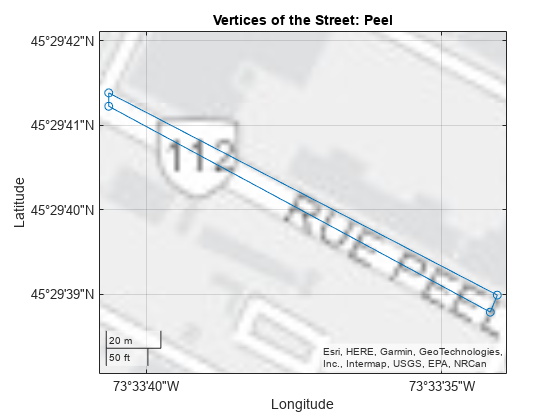

UE_grid = cell(1,2);
UE_grid{1}.street = 'Peel'; 
    UE_grid{1}.vertice{1}.location = [45.494785,-73.561332]; % lat, lon
    UE_grid{1}.vertice{2}.location = [45.494829,-73.561287];
    UE_grid{1}.vertice{3}.location = [45.494164,-73.559462];
    UE_grid{1}.vertice{4}.location = [45.494108,-73.559495];
UE_grid{2}.street = 'William'; 
    UE_grid{2}.vertice{1}.location = [45.495371,-73.560918];
    UE_grid{2}.vertice{2}.location = [45.495328,-73.560852];
    UE_grid{2}.vertice{3}.location = [45.494852,-73.561230];
    UE_grid{2}.vertice{4}.location = [45.494862,-73.561259];

% Extract coordinates from UE_grid
latitudes = [UE_grid{1}.vertice{1}.location(1), UE_grid{1}.vertice{2}.location(1), ...
             UE_grid{1}.vertice{3}.location(1), UE_grid{1}.vertice{4}.location(1), ...
             UE_grid{1}.vertice{1}.location(1)]; % Closing the loop
longitudes = [UE_grid{1}.vertice{2}.location(2), UE_grid{1}.vertice{2}.location(2), ...
              UE_grid{1}.vertice{3}.location(2), UE_grid{1}.vertice{4}.location(2), ...
              UE_grid{1}.vertice{2}.location(2)]; % Closing the loop

% Create a geographic plot
figure;
geoplot(latitudes, longitudes, '-o');
title('Vertices of the Street: Peel');
grid on;

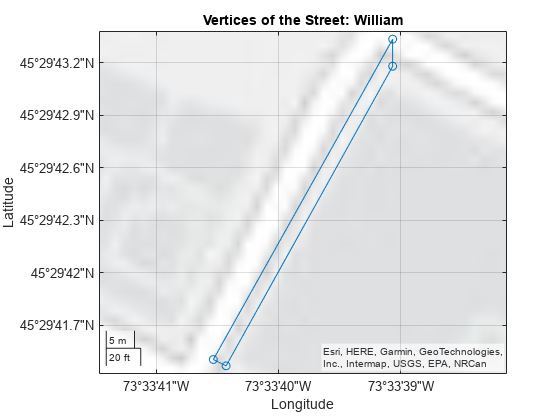



% Extract coordinates from UE_grid
latitudes = [UE_grid{2}.vertice{1}.location(1), UE_grid{2}.vertice{2}.location(1), ...
             UE_grid{2}.vertice{3}.location(1), UE_grid{2}.vertice{4}.location(1), ...
             UE_grid{2}.vertice{1}.location(1)]; % Closing the loop
longitudes = [UE_grid{2}.vertice{2}.location(2), UE_grid{2}.vertice{2}.location(2), ...
              UE_grid{2}.vertice{3}.location(2), UE_grid{2}.vertice{4}.location(2), ...
              UE_grid{2}.vertice{2}.location(2)]; % Closing the loop

% Create a geographic plot
figure;
geoplot(latitudes, longitudes, '-o');
title('Vertices of the Street: William');
grid on;

fc = 6e9;                             % carrier frequency (Hz)
bsPosition = [45.494449,-73.561667];  % lat, lon
bsAntSize = [1 1]; % [8 8];                    % number of rows and columns in rectangular array (base station)
bsArrayOrientation = [-30 0].';       % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards) in deg

reflectionsOrder = 1;                 % number of reflections for ray tracing analysis (0 for LOS)
 
% Bandwidth configuration, required to set the channel sampling rate and for perfect channel estimation
SCS = 30; % 15; % subcarrier spacing
NRB = 51; % number of resource blocks, SCS*NRB*12 MHz bandwidth for transmission


## Import and Visualize 3-D Environment with Buildings for Ray Tracing

Launch Site Viewer with buildings in ETS. For more information about the osm file, see [1].

if exist('viewer','var') && isvalid(viewer) % viewer handle exists and viewer window is open
    clearMap(viewer);
else
    viewer = siteviewer("Basemap","openstreetmap","Buildings","map.osm");    
end

## Create Base Station and UE

Locate the base station and the UE on the map.

bsSite = txsite("Name","Base station", ...
    "Latitude",bsPosition(1),"Longitude",bsPosition(2),...
    "AntennaAngle",bsArrayOrientation(1:2),...
    "AntennaHeight",4,...  % in m
    "TransmitterFrequency",fc);
show(bsSite);

Modify the code so that we can have each vertex has its own rays

ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
for idx_grid = 1:length(UE_grid)
    for idx_vert = 1:4
        % UEs
        UE_grid{idx_grid}.vertice{idx_vert}
        uePosition = UE_grid{idx_grid}.vertice{idx_vert}.location; % lat, lon
        
        ueSite = rxsite("Name","UE1", ...
            "Latitude",uePosition(1),"Longitude",uePosition(2),...
            "AntennaHeight",1,... % in m
            "AntennaAngle",ueArrayOrientation(1:2));
        % Visualize the location of the base station and the UE. The base station is on top of a building.
        show(ueSite);
        pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
        rays = raytrace(bsSite,ueSite,pm,"Type","pathloss");
        % checking if each BS-UE link contains LOS
        if rays{1}(1).LineOfSight == 0
            error("Should be LOS");  % stop checking
        end
        plot(rays{1});
    end
end

ans = struct with fields:
    location: [45.4948 -73.5613]

ans = struct with fields:
    location: [45.4948 -73.5613]

ans = struct with fields:
    location: [45.4942 -73.5595]

ans = struct with fields:
    location: [45.4941 -73.5595]

ans = struct with fields:
    location: [45.4954 -73.5609]

ans = struct with fields:
    location: [45.4953 -73.5609]

ans = struct with fields:
    location: [45.4949 -73.5612]

ans = struct with fields:
    location: [45.4949 -73.5613]

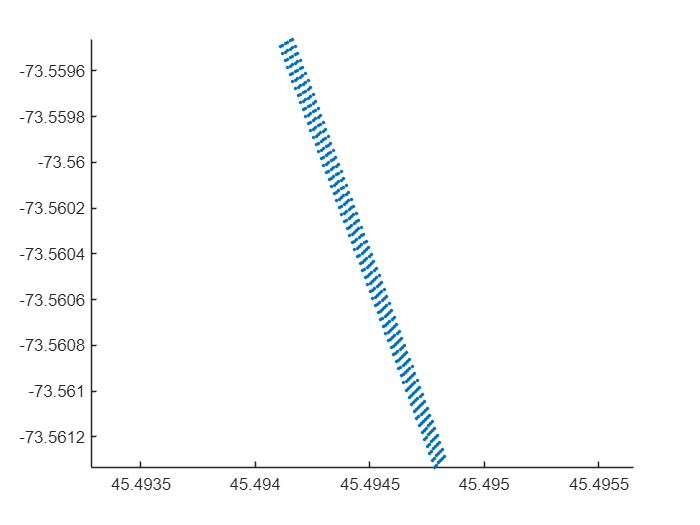

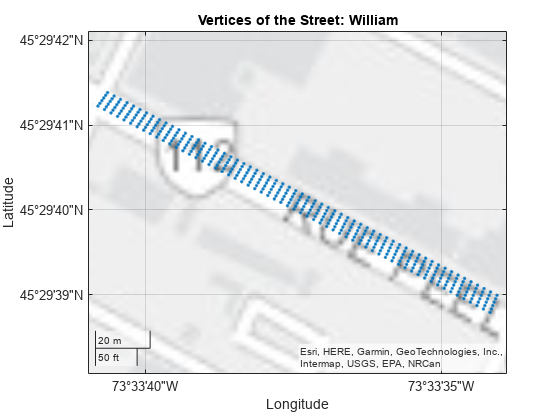

UE_grid{1}.pointInside = gen_pointInside(UE_grid{1}, 5, 60); % in Peel street

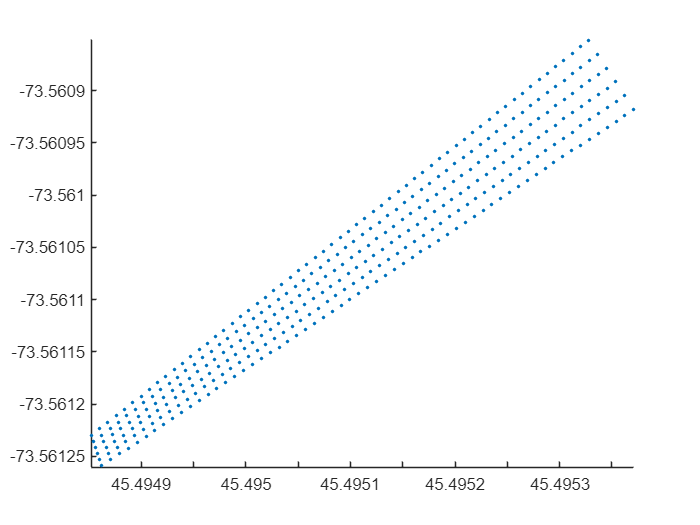

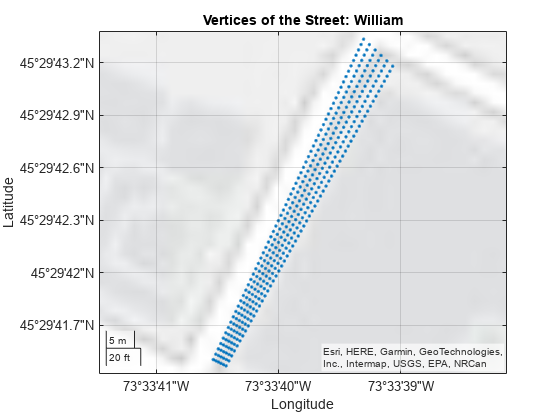

UE_grid{2}.pointInside = gen_pointInside(UE_grid{2}, 5, 60); % William street

dbstop if error
% Loop over all inside points to check if they are LOS or not

ueAntSize = [1 1]; % [2 2];                    % number of rows and columns in rectangular array (UE).
ueArrayOrientation = [180 45].';      % azimuth (0 deg is East, 90 deg is North) and elevation (positive points upwards)  in deg
pm = propagationModel("raytracing","Method","sbr","MaxNumReflections",reflectionsOrder);
for idx_grid = 1:length(UE_grid)
    for idx_point = 1:size(UE_grid{idx_grid}.pointInside,1)
        % UEs
        uePosition = UE_grid{idx_grid}.pointInside(idx_point,:); % lat, lon

        ueSite = rxsite("Name","UE1", ...
            "Latitude",uePosition(1),"Longitude",uePosition(2),...
            "AntennaHeight",1,... % in m
            "AntennaAngle",ueArrayOrientation(1:2));
        UE_grid{idx_grid}.rays{idx_point} = raytrace(bsSite,ueSite,pm,"Type","pathloss");
        % checking if each BS-UE link contains LOS
        % if UE_grid{idx_grid}.rays{idx_point}{1}(1).LineOfSight == 0
        if ~any([rays{1}.LineOfSight])
            fprintf('UE_idx = %d',idx_point);
            error("Should be LOS");  % stop checking
        end
        % plot(rays{1});
        if ~mod(idx_point,100)
            fprintf('%d \n', idx_point);
        end
    end
end

100 
200 
300 
100 
200 
300 


Generate points inside the quadrilateral

function points = gen_pointInside(UE_grid_n, num_div_x, num_div_y) % lat, lon
    A = UE_grid_n.vertice{1}.location;
    B = UE_grid_n.vertice{2}.location;
    C = UE_grid_n.vertice{3}.location;
    D = UE_grid_n.vertice{4}.location;

    % Generate points inside the quadrilateral
    points = zeros(num_div_x * num_div_y, 2);  % Preallocate for efficiency
    index = 1;

    for i = 0:num_div_x
        for j = 0:num_div_y
            % Interpolation along the x-direction
            P1_x = (1 - i/num_div_x) * A(1) + (i/num_div_x) * B(1);
            P1_y = (1 - i/num_div_x) * A(2) + (i/num_div_x) * B(2);

            P2_x = (1 - i/num_div_x) * D(1) + (i/num_div_x) * C(1);
            P2_y = (1 - i/num_div_x) * D(2) + (i/num_div_x) * C(2);

            % Interpolation along the y-direction
            point_x = (1 - j/num_div_y) * P1_x + (j/num_div_y) * P2_x;
            point_y = (1 - j/num_div_y) * P1_y + (j/num_div_y) * P2_y;

            points(index, :) = [point_x, point_y];
            index = index + 1;
        end
    end
    % Display the points (optional)
    scatter(points(:,1), points(:,2), '.');
    axis equal;

    figure;
    geoplot(points(:,1), points(:,2), '.');
    title('Vertices of the Street: William');
    grid on;
end
